# El mapa de Beurger

#### Ecuaciones del mapa

El **mapa de Burgers** es un sistema dinámico no lineal que describe la evolución de dos variables, $x$ e $y$, a través de las siguientes ecuaciones iterativas:

### 
$$x_{n+1} =\left(1-\eta \;\right)x_n -y_n^2$$


### 
$$y_{n+1} =\left(1+\mu \;\right)y_n +x_n y_n$$


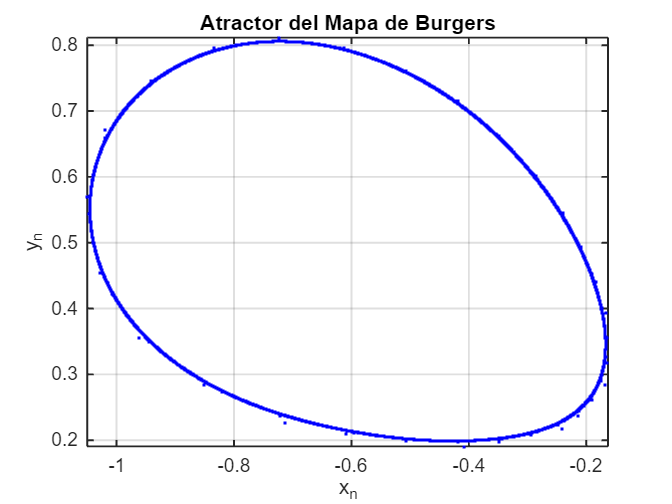

clear all
close all

% Parámetros del mapa de Burgers
eta = 0.5; % Parámetro del mapa
mu = 0.55; % Parámetro del mapa
x0 = 0.1; % Condición inicial para x
y0 = 0.1; % Condición inicial para y

% Número de iteraciones
N = 6000;

% Inicialización de vectores
x = zeros(N+1, 1); % Coordenada x
y = zeros(N+1, 1); % Coordenada y

% Asignación de condiciones iniciales
x(1) = x0;
y(1) = y0;


% Aplicar el mapa de Burgers de forma iterativa
for n = 1:N
    % Para la primera trayectoria
    x(n+1) = (1 - eta) * x(n) - (y(n))^2;
    y(n+1) = (1 + mu) * y(n) + x(n) * y(n);

end

% Gráfica 1: Atractor en el espacio de fases
figure;
plot(x(50:end), y(50:end), 'b.', 'MarkerSize', 6); 
title('Atractor del Mapa de Burgers', 'FontSize', 15, 'FontWeight', 'bold');
xlabel('x_n', 'FontSize', 15);
ylabel('y_n', 'FontSize', 15);
grid on;
set(gca, 'FontSize', 12, 'LineWidth', 1.2); % Personalización de la gráfica
axis tight; % Ajustar los límites de los ejes

# Sensibilidad a las condiciones iniciales

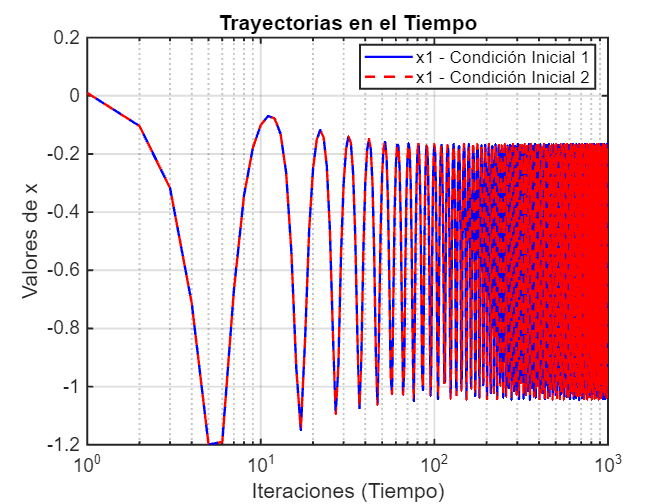

N = 1000; % Número de iteraciones
t = 0:N; % Vector de tiempo

% Condiciones iniciales
x0 = 0.1; % Valor inicial de x
y0 = 0.2; % Valor inicial de y

% Inicialización de vectores para dos condiciones iniciales

x1 = zeros(N+1, 1); % Coordenada x para la primera trayectoria
y1 = zeros(N+1, 1); % Coordenada y para la primera trayectoria

x2 = zeros(N+1, 1); % Coordenada x para la segunda trayectoria
y2 = zeros(N+1, 1); % Coordenada y para la segunda trayectoria

% Asignación de condiciones iniciales
x1(1) = x0;
y1(1) = y0;

x2(1) = x0 + 1e-9; % Condición inicial ligeramente diferente
y2(1) = y0;
% Generación de las trayectorias con las dos condiciones iniciales
for n = 1:N
    x1(n+1) = (1 - eta) * x1(n) - (y1(n))^2;
    y1(n+1) = (1 + mu) * y1(n) + x1(n) * y1(n);
    
    x2(n+1) = (1 - eta) * x2(n) - (y2(n))^2;
    y2(n+1) = (1 + mu) * y2(n) + x2(n) * y2(n);
end

% Trayectoria de la primera condición inicial
figure;
semilogx(t, x1, 'b-', 'LineWidth', 1.5); hold on
% Trayectoria de la segunda condición inicial
semilogx(t, x2, 'r--', 'LineWidth', 1.5); 

title('Trayectorias en el Tiempo', 'FontSize', 15, 'FontWeight', 'bold');
xlabel('Iteraciones (Tiempo)', 'FontSize', 15);
ylabel('Valores de x', 'FontSize', 15);
legend({'x1 - Condición Inicial 1', 'x1 - Condición Inicial 2'}, 'Location', 'Best');
grid on;
set(gca, 'FontSize', 12, 'LineWidth', 1.2); % Personalización de la gráfica